Limpar 

close all
clear
clc

# Analise CC para emisro comum com polarização por divisor de tensão

Figura 1- Circuito base

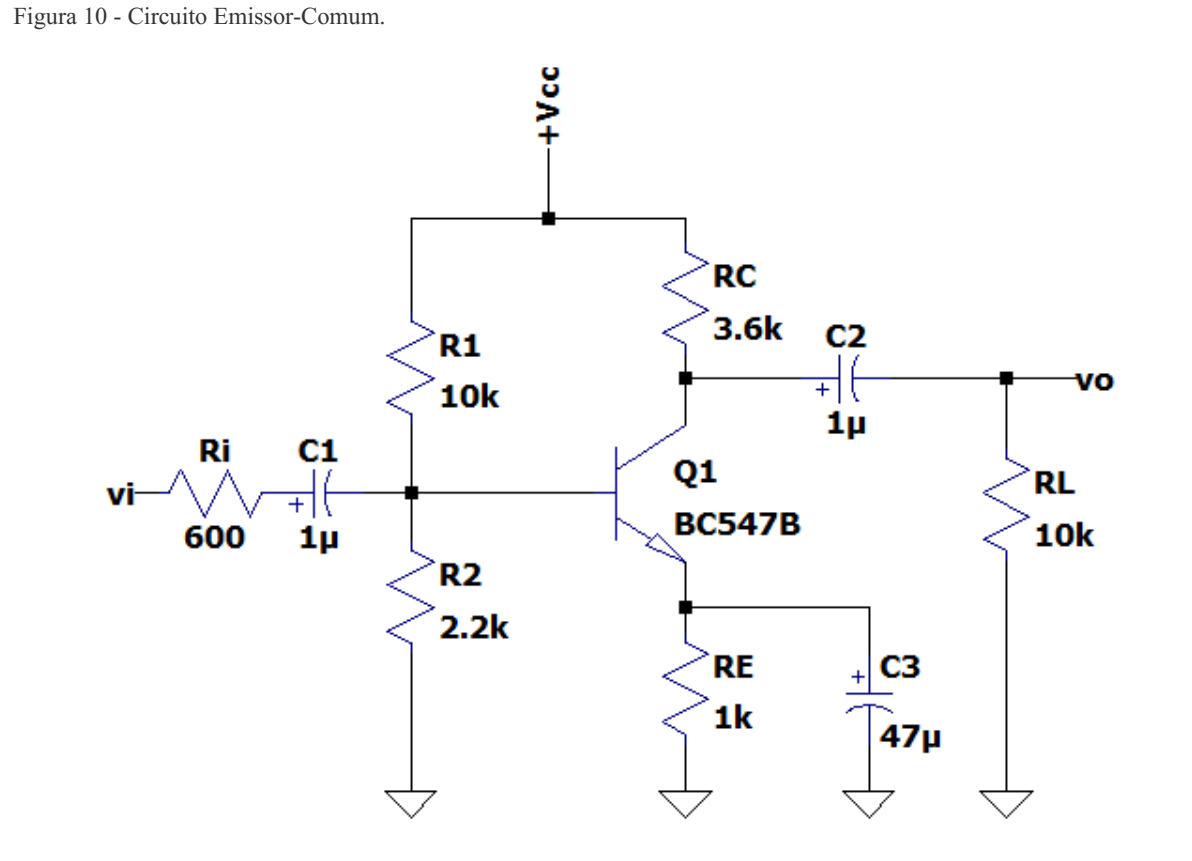

## ** Calc Analise CC (DC)**

Figura 2- Circuito para analise CC

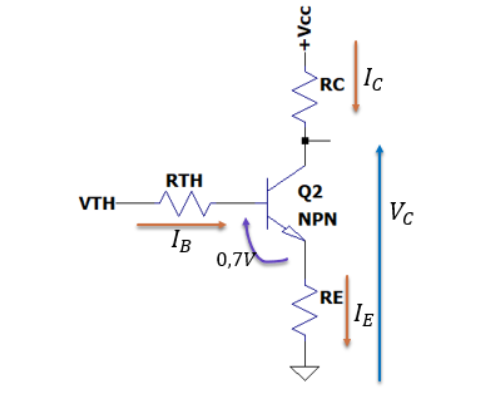

### Valores dos componentes:

R1 = 100e+3;%%Rth
R2 =25e+3;%%Rth
RE = 100;%%
Vcc = 18;%%Variavel de entrada
B = 290; % Beta para o calc
Vbe = 0.7; 
Vce = 5; %data sheet


### Equivalentes de TH

Vth = (R2/(R1+R2))*Vcc

Vth = 3.6000

Rth = ((1/R1)+(1/R2))^-1

Rth = 20000

### Correntes

IB = (Vth-Vbe)/(Rth+RE*(B+1))

IB = 5.9063e-05

IC = (B+1)*IB

IC = 0.0172

IE = IC

IE = 0.0172

### Tensões CC

Vb = Vth

Vb = 3.6000

Ve = Vb-Vbe

Ve = 2.9000

Vc = Vce+Ve

Vc = 7.9000

## **Calc Analise CA (AC)**

Figura 3- Circuito para analise CA

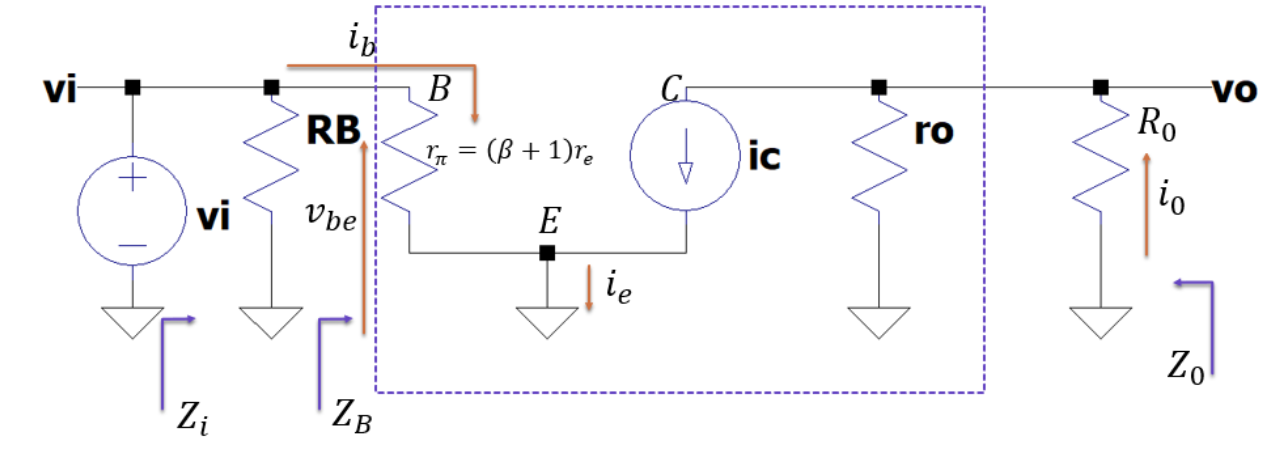

### Valores dos componentes 

*Obs.: todos os valores de componentes possuem a variavel com nome correspondente ao circuito apresentado na figura 1.

Ri = 100; %valor de entrada da figura 1
RL = 1.3e+3;%valor de entrada da figura 1
RC = 600;%valor de entrada da figura 1
RB = Rth; %calculado
R0 = ((1/RC)+(1/RL))^-1%calculado R0

R0 = 410.5263

VT = 25e-3;%% Tensão termica dado no datasheet VT = (K*T)/q
vi = 35e-3

vi = 0.0350

### calculo do re e rpi:

re = VT/IE

re = 1.4546

rpi = (B+1)*re

rpi = 423.2759

### **Calculo para CA**

Av = -R0/re

Av = -282.2348

Z0 = R0

Z0 = 410.5263

Zi = Ri+((RB*re*B)/(RB+re*B))

Zi = 513.1084

fl = 20;
C1 = (1/2*pi)*(1/(0.1*fl*Ri+((1/R1)+(1/R2)+(1/B*re))^-1))

C1 = 0.0040

C2 = (1/2*pi)*(1/(0.8*fl*(((1/RE)+1/((re+((1/R1)+(1/R2)+(1/Ri))^-1)))^-1)))

C2 = 0.0020

C3 = (1/2*pi)*(1/(0.1*fl*(RC+RL)))

C3 = 4.1337e-04